Code to find Tau values: 

%naming convention for step inputs -- in volts, data_ab = step input of a.b
%volts
data_n5 = load("step_input_-5.mat","Y","U","T");
data_n4 = load("step_input_-4.mat","Y","U","T");
data_n3 = load("step_input_-3.mat","Y","U","T");
data_n2 = load("step_input_-2.mat","Y","U","T");
data_n1 = load("step_input_-1.mat","Y","U","T");
data_p1 = load("step_input_1.mat","Y","U","T");
data_p2 = load("step_input_2.mat","Y","U","T");
data_p3 = load("step_input_3.mat","Y","U","T");
data_p4 = load("step_input_4.mat","Y","U","T");
data_p5 = load("step_input_5.mat","Y","U","T");

data_array = [data_n5, data_n4, data_n3, data_n2, data_n1, data_p1, data_p2, data_p3, data_p4, data_p5]

data_array = 1×10 struct array with fields:
    Y
    U
    T


Step_Inputs = [-5 -4 -3 -2 -1 1 2 3 4 5]'

Step_Inputs =     -5
    -4
    -3
    -2
    -1
     1
     2
     3
     4
     5


tau_array = [0 0 0 0 0 0 0 0 0 0]

tau_array =      0     0     0     0     0     0     0     0     0     0


k_array = [0 0 0 0 0 0 0 0 0 0]

k_array =      0     0     0     0     0     0     0     0     0     0




for i = 1:10
    tau_array(i) = get_tau(data_array(i).Y, data_array(i).T, data_array(i).U)
    k_array(i) = get_k(data_array(i).Y, data_array(i).T, data_array(i).U)
end

threshold = -0.8309

tau = 0.1950

Estimated Time Constant (tau): 0.195 seconds


tau_array =     0.1950         0         0         0         0         0         0         0         0         0


Calculated Gain (K): -0.46009


k_array =    -0.4601         0         0         0         0         0         0         0         0         0


threshold = -0.6726

tau = 0.1980

Estimated Time Constant (tau): 0.198 seconds


tau_array =     0.1950    0.1980         0         0         0         0         0         0         0         0


Calculated Gain (K): -0.56994


k_array =    -0.4601   -0.5699         0         0         0         0         0         0         0         0


threshold = -0.8230

tau = 0

Estimated Time Constant (tau): 0 seconds


tau_array =     0.1950    0.1980         0         0         0         0         0         0         0         0


Calculated Gain (K): 1.2023


k_array =    -0.4601   -0.5699    1.2023         0         0         0         0         0         0         0


threshold = 1.5871

tau = 0

Estimated Time Constant (tau): 0 seconds


tau_array =     0.1950    0.1980         0         0         0         0         0         0         0         0


Calculated Gain (K): 0.57455


k_array =    -0.4601   -0.5699    1.2023    0.5746         0         0         0         0         0         0


threshold = 1.5230

tau = 0.7380

Estimated Time Constant (tau): 0.738 seconds


tau_array =     0.1950    0.1980         0         0    0.7380         0         0         0         0         0


Calculated Gain (K): -1.9127


k_array =    -0.4601   -0.5699    1.2023    0.5746   -1.9127         0         0         0         0         0


threshold = -0.1449

tau = 0.0030

Estimated Time Constant (tau): 0.003 seconds


tau_array =     0.1950    0.1980         0         0    0.7380    0.0030         0         0         0         0


Calculated Gain (K): -1.8334


k_array =    -0.4601   -0.5699    1.2023    0.5746   -1.9127   -1.8334         0         0         0         0


threshold = -0.1828

tau = 0.6390

Estimated Time Constant (tau): 0.639 seconds


tau_array =     0.1950    0.1980         0         0    0.7380    0.0030    0.6390         0         0         0


Calculated Gain (K): 0.64624


k_array =    -0.4601   -0.5699    1.2023    0.5746   -1.9127   -1.8334    0.6462         0         0         0


threshold = -1.3953

tau = 0

Estimated Time Constant (tau): 0 seconds


tau_array =     0.1950    0.1980         0         0    0.7380    0.0030    0.6390         0         0         0


Calculated Gain (K): -0.66061


k_array =    -0.4601   -0.5699    1.2023    0.5746   -1.9127   -1.8334    0.6462   -0.6606         0         0


threshold = -2.1151

tau = 0.0870

Estimated Time Constant (tau): 0.087 seconds


tau_array =     0.1950    0.1980         0         0    0.7380    0.0030    0.6390         0    0.0870         0


Calculated Gain (K): 0.21966


k_array =    -0.4601   -0.5699    1.2023    0.5746   -1.9127   -1.8334    0.6462   -0.6606    0.2197         0


threshold = -0.1251

tau = 0.0930

Estimated Time Constant (tau): 0.093 seconds


tau_array =     0.1950    0.1980         0         0    0.7380    0.0030    0.6390         0    0.0870    0.0930


Calculated Gain (K): 0.76479


k_array =    -0.4601   -0.5699    1.2023    0.5746   -1.9127   -1.8334    0.6462   -0.6606    0.2197    0.7648


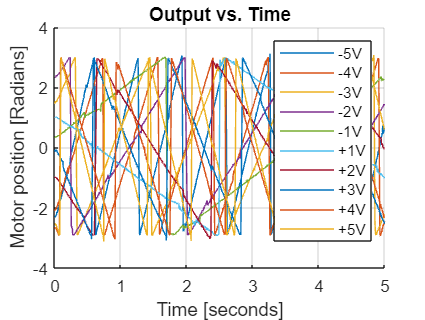


figure;
hold on; 
for i = 1:10
    plot(data_array(i).T, data_array(i).Y); 
end 

grid on;
title('Output vs. Time');
ylabel('Motor position [Radians]'); 
xlabel('Time [seconds]');
legend('-5V', '-4V', '-3V', '-2V', '-1V', ...
     '+1V', '+2V', '+3V', '+4V', '+5V')

hold off;

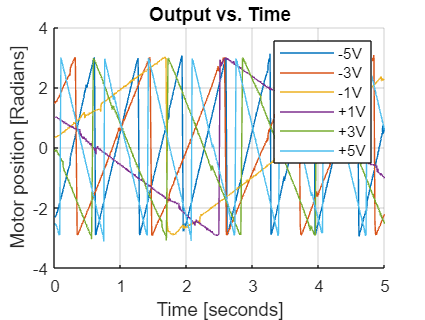


figure;
hold on; %356L code skipped a few, so will I
plot(data_array(1).T, data_array(1).Y); 
plot(data_array(3).T, data_array(3).Y); 
plot(data_array(5).T, data_array(5).Y); 
plot(data_array(6).T, data_array(6).Y); 
plot(data_array(8).T, data_array(8).Y); 
plot(data_array(10).T, data_array(10).Y); 

grid on;
title('Output vs. Time');
ylabel('Motor position [Radians]'); 
xlabel('Time [seconds]');
legend('-5V', '-3V', '-1V', '+1V', '+3V','+5V')
    
hold off;


disp('Plotting complete.');

Plotting complete.



Tau = tau_array';
K = k_array';
data = table(Step_Inputs, Tau, K);

k_linear_range = [k_array(6:10)];
tau_linear_range = [tau_array(6:10)];

model_k = mean(k_linear_range);
model_tau = mean(tau_linear_range);

[break]

s = tf('s');

Unrecognized function or variable 'tf'.

P = model_k/(model_tau*s+1)
model_pole = pole(P)

figure;
hold on;
scatter(Step_Inputs, tau_array,"filled")
scatter(Step_Inputs, k_array,"filled")
grid on;    
title('Calculated K and Tau vs Step Inputs');
xlabel('Step Input (Volts)');
legend("Tau", "K");
hold off


function[tau] = get_tau(Y, T, U)

final_value = mean(Y(end-50:end)); % Steady-state value (assuming system settled)
initial_value = Y(1);
threshold = 0.632 * (final_value-initial_value) + initial_value

index = find(Y >= threshold, 1); % Find index where Y crosses threshold
tau = T(index)

disp(['Estimated Time Constant (tau): ', num2str(tau), ' seconds']);

end

function[k] = get_k(Y, T, U)

k = (mean(Y(end-50:end)) - Y(1)) / U(1);
disp(['Calculated Gain (K): ', num2str(k)]);
end